clear all; close all;

% A = 1;
% B = 1;
% C = 0.56532;

A = 0.32345;
B = -0.78743;
C = 0.56532;

Y = (A + B) * C; 

sign=1; %0-unsigned value, 1-signed value % sign
prec_i=1; %number of integer part bits (Nc) % one bit
prec_f=7; %number of fractional part bits (Nu) % eight bits
word = 1 + prec_i + prec_f; % whole word

res = zeros(1, 17);
for prec_f = 0:16
    word = 1 + prec_i + prec_f;
    a_fix = fi(A,sign,word,prec_f);
    a_d = double(a_fix);
    b_fix = fi(B,sign,word,prec_f);
    b_d = double(b_fix);
    c_fix = fi(C,sign,word,prec_f);
    c_d = double(c_fix);
    y_d = (a_d + b_d) * c_d;
    res(prec_f+1) = abs(y_d - Y);
end

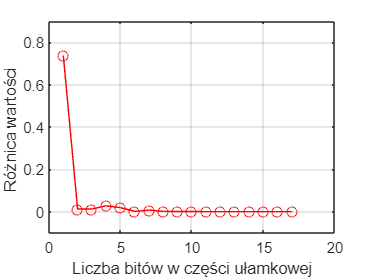

res;
figure(1)
plot(res, '-or')
ylim ([-0.1 0.9]);
grid
xlabel ('Liczba bitów w części ułamkowej')
ylabel ('Różnica wartości ');

  prec_f=7

prec_f = 7

  sign=1; %0-unsigned value, 1-signed value % sign
prec_i=1; %number of integer part bits (Nc) % one bit
prec_f=7; %number of fractional part bits (Nu) % eight bits
word = 1 + prec_i + prec_f; % whole word

a_fix = fi(A,sign,word,prec_f);
 b_fix = fi(B,sign,word,prec_f);
 c_fix = fi(C,sign,word,prec_f);
 
 a_d = double(a_fix);
 b_d = double(b_fix);
 c_d = double(c_fix);
y_f=(a_fix+b_fix)*c_fix

y_f =    -0.2637

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 19
        FractionLength: 14


 
 y_d = (a_d + b_d) * c_d

y_d = -0.2637


bin(a_fix) %do analizy reprezentacji binarnej

ans = '000101001'

bin(b_fix) %do analizy reprezentacji binarnej

ans = '110011011'

bin(c_fix) %do analizy reprezentacji binarnej

ans = '001001000'